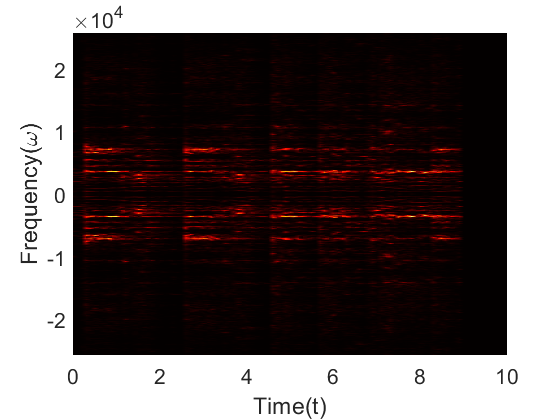

clear; close all; clc

load handel
S = y';
n = length(S);
t2 = (1:length(S))/Fs;
t = t2(1:n); 
L = t(end);
k=(2*pi/L)*[0:n/2 -n/2:-1]; 
ks=fftshift(k);


tau = 3;
a = 1000;

figure(2)
tslide=0:0.1:10;
Sgt_spec = zeros(length(tslide),n);
for j=1:length(tslide)
    g=exp(-a*(t-tslide(j)).^2); 
    Sg=g.*S; 
    Sgt=fft(Sg); 
    Sgt_spec(j,:) = fftshift(abs(Sgt)); % We don't want to scale it
end
pcolor(tslide,ks,Sgt_spec.'), 
shading interp 
set(gca,'Fontsize',16) 
colormap(hot)
xlabel('Time(t)')
ylabel('Frequency(\omega)')

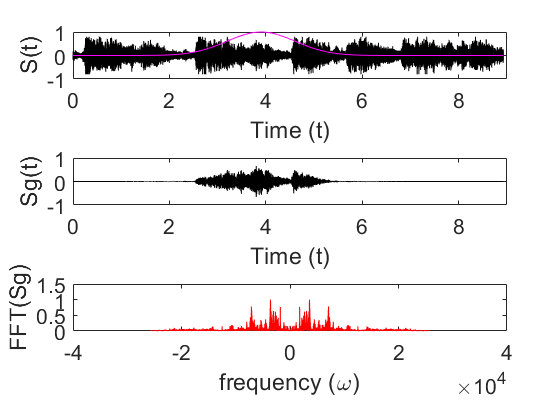

figure(3)
a = 1;
tslide=0:0.1:10;

for j=1:length(tslide)
    g=exp(-a*(t-tslide(j)).^2);  
    Sg=g.*S; 
    Sgt=fft(Sg); 
    
    subplot(3,1,1) 
    plot(t,S,'k') 
    hold on 
    plot(t,g,'m')
    hold off
    set(gca,'Fontsize',16), xlabel('Time (t)'), ylabel('S(t)'), axis([0 9 -1 1])

    subplot(3,1,2) 
    plot(t,Sg,'k') 
    set(gca,'Fontsize',16), xlabel('Time (t)'), ylabel('Sg(t)'), axis([0 9 -1 1])

    subplot(3,1,3) 
    plot(ks,abs(fftshift(Sgt))/max(abs(Sgt)),'r'); axis([-40000 40000 0 1.5])
    set(gca,'Fontsize',16)
    xlabel('frequency (\omega)'), ylabel('FFT(Sg)')
    drawnow
    pause(0.1)
end

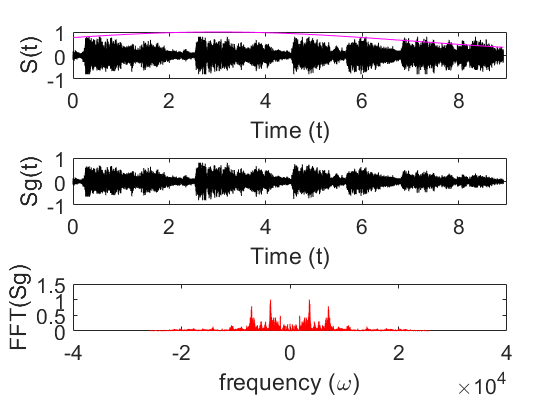

figure(4)
tau = 3;
k = 1:100;
y = 0.001.*exp(k/5);
aslide=y;

for j=1:length(aslide)
    g=exp(-aslide(j)*(t-tau).^2);  
    Sg=g.*S; 
    Sgt=fft(Sg); 
    
    subplot(3,1,1) 
    plot(t,S,'k') 
    hold on 
    plot(t,g,'m')
    hold off
    set(gca,'Fontsize',16), xlabel('Time (t)'), ylabel('S(t)'), axis([0 9 -1 1])

    subplot(3,1,2) 
    plot(t,Sg,'k') 
    set(gca,'Fontsize',16), xlabel('Time (t)'), ylabel('Sg(t)'), axis([0 9 -1 1])

    subplot(3,1,3) 
    plot(ks,abs(fftshift(Sgt))/max(abs(Sgt)),'r'); axis([-40000 40000 0 1.5])
    set(gca,'Fontsize',16)
    xlabel('frequency (\omega)'), ylabel('FFT(Sg)')
    drawnow
    pause(0.1)
end

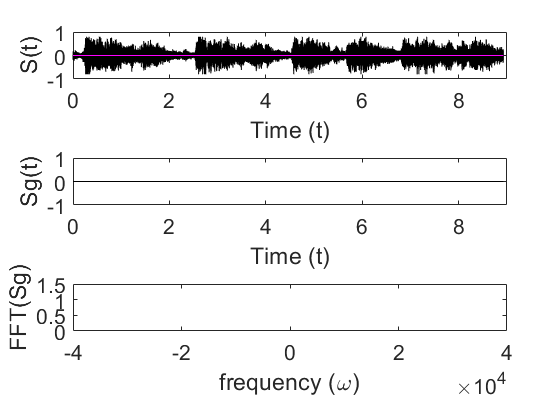


figure(5)
a = 1000;

tslide=0:0.1:10;

for j=1:length(tslide)
    t0 = tslide(j);
    mex = (1-a.*(t-t0).^2).*exp(-a.*(t-t0).^2);
    Sg=mex.*S; 
    Sgt=fft(Sg); 
    
    subplot(3,1,1) 
    plot(t,S,'k') 
    hold on 
    plot(t,mex,'m')
    hold off
    set(gca,'Fontsize',16), xlabel('Time (t)'), ylabel('S(t)'), axis([0 9 -1 1])

    subplot(3,1,2) 
    plot(t,Sg,'k') 
    set(gca,'Fontsize',16), xlabel('Time (t)'), ylabel('Sg(t)'), axis([0 9 -1 1])

    subplot(3,1,3) 
    plot(ks,abs(fftshift(Sgt))/max(abs(Sgt)),'r'); axis([-40000 40000 0 1.5])
    set(gca,'Fontsize',16)
    xlabel('frequency (\omega)'), ylabel('FFT(Sg)')
    drawnow
    pause(0.1)
end

a=10000000;
figure(2)
tslide=0:0.1:10;
Sgt_spec = zeros(length(tslide),n);
for j=1:length(tslide)
    mex = (1-a.*(t-t0).^2).*exp(-a.*(t-t0).^2);
    Sg=mex.*S; 
    Sgt=fft(Sg); 
    Sgt_spec(j,:) = fftshift(abs(Sgt)); % We don't want to scale it
end
pcolor(tslide,ks,Sgt_spec.'), 
shading interp 
set(gca,'Fontsize',16) 
colormap(hot)
xlabel('Time(t)')
ylabel('Frequency(\omega)')

figure(6)
a = 1;
tslide=0:0.1:9;

for j=1:length(tslide)
    t0 = tslide(j);
    y = abs(t-tslide(j))<=a;
    Sg=y.*S; 
    Sgt=fft(Sg); 
    
    subplot(3,1,1) 
    plot(t,S,'k') 
    hold on 
    plot(t,y,'m')
    hold off
    set(gca,'Fontsize',16), xlabel('Time (t)'), ylabel('S(t)'), axis([0 9 -1 1])

    subplot(3,1,2) 
    plot(t,Sg,'k') 
    set(gca,'Fontsize',16), xlabel('Time (t)'), ylabel('Sg(t)'), axis([0 9 -1 1])

    subplot(3,1,3) 
    plot(ks,abs(fftshift(Sgt))/max(abs(Sgt)),'r'); axis([-40000 40000 0 1.5])
    set(gca,'Fontsize',16)
    xlabel('frequency (\omega)'), ylabel('FFT(Sg)')
    drawnow
    pause(0.1)
end

a=1;
figure(2)
tslide=0:0.1:10;
Sgt_spec = zeros(length(tslide),n);
for j=1:length(tslide)
    t0 = tslide(j);
    y = abs(t-tslide(j))<=a;
    Sg=y.*S; 
    Sgt=fft(Sg); 
    Sgt_spec(j,:) = fftshift(abs(Sgt)); % We don't want to scale it
end
pcolor(tslide,ks,Sgt_spec.'), 
shading interp 
set(gca,'Fontsize',16) 
colormap(hot)
xlabel('Time(t)')
ylabel('Frequency(\omega)')

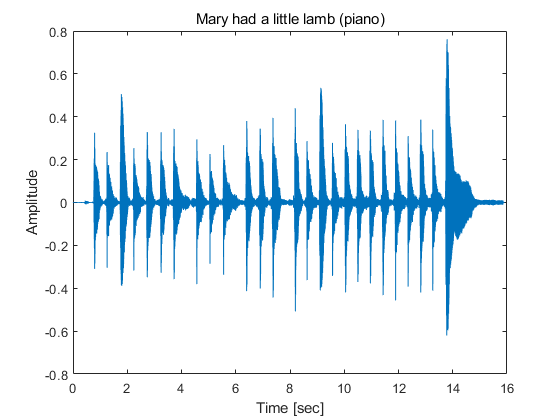

figure(7)
[y,Fs] = audioread('music1.wav');
tr_piano=length(y)/Fs; % record time in seconds
plot((1:length(y))/Fs,y);
xlabel('Time [sec]'); ylabel('Amplitude');
title('Mary had a little lamb (piano)');
p8 = audioplayer(y,Fs); playblocking(p8);

figure(7)
[y,Fs] = audioread('music1.wav');
tr_piano=length(y)/Fs; % record time in seconds
plot((1:length(y))/Fs,y);
xlabel('Time [sec]'); ylabel('Amplitude');
title('Mary had a little lamb (piano)');

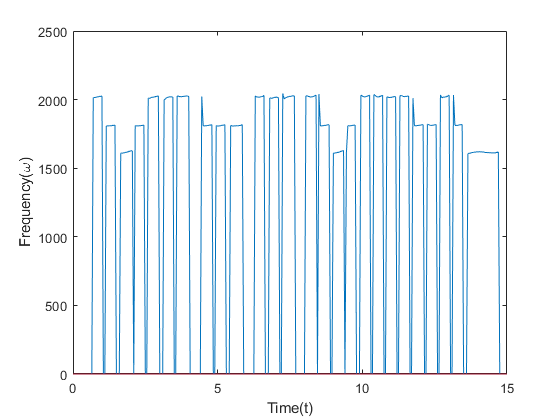



a = 100;
tslide=0:0.05:15;
S = y';
n = length(S);
t2 = (1:length(S))/Fs;
t = t2(1:n); 
L = t(end);
k=(2*pi/L)*[0:n/2-1 -n/2:-1]; 
ks=fftshift(k);

score = zeros(length(tslide));
for j=1:length(tslide)
    t0 = tslide(j);
    g=exp(-a*(t-tslide(j)).^2);  
    Sg=g.*S; 
    Sgt=fft(Sg); 
    y = Sg(find(Sg==max(Sg)));
    if y >=0.05
        x = k(find(Sgt==max(Sgt)));
        score(j) = abs(x);
    end

end
figure(8)
plot(tslide, score);
xlabel('Time(t)')
ylabel('Frequency(\omega)')

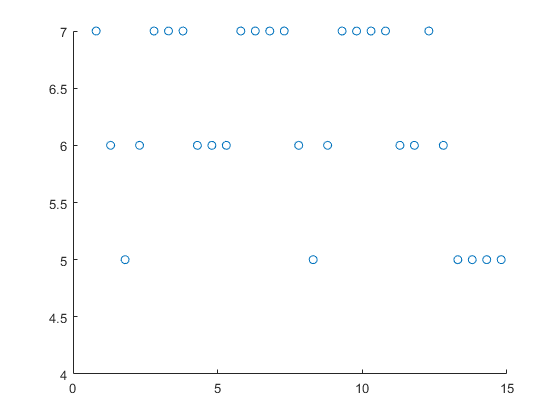

t = 0.8:0.5:14.8;
y = [7,6,5,6,7,7,7,6,6,6,7,7,7,7,6,5,6,7,7,7,7,6,6,7,6,5,5,5,5];
node = ['A', 'B', 'C', 'D', 'E', 'F','G'];
scatter(t, y);
ylim([4 7])

set('XTickLabel', x, 'YTickLabel', node)

错误使用 set
句柄无效

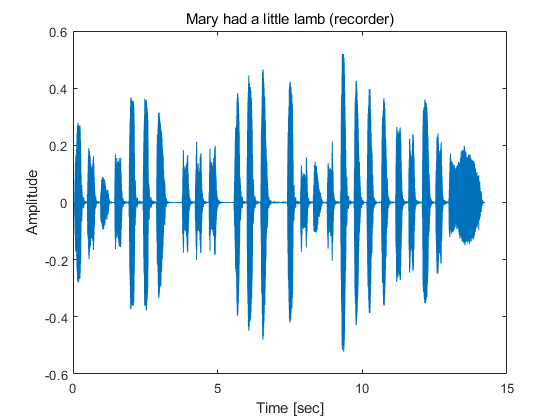

figure(9)
[y,Fs] = audioread('music2.wav');
tr_rec=length(y)/Fs; % record time in seconds
plot((1:length(y))/Fs,y);
xlabel('Time [sec]'); ylabel('Amplitude');
title('Mary had a little lamb (recorder)');

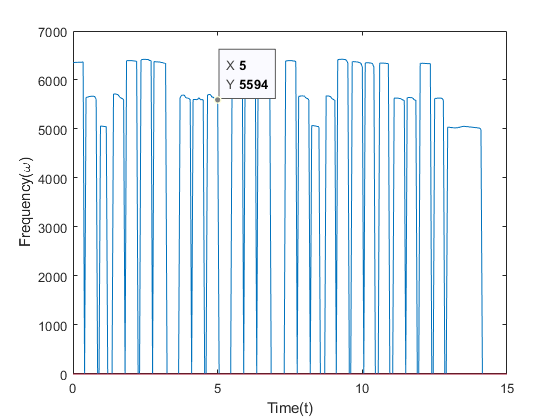


a = 100;
tslide=0:0.05:15;
S = y';
n = length(S);
t2 = (1:length(S))/Fs;
t = t2(1:n); 
L = t(end);
k=(2*pi/L)*[0:n/2-1 -n/2:-1]; 
ks=fftshift(k);

score = zeros(length(tslide));
for j=1:length(tslide)
    t0 = tslide(j);
    g=exp(-a*(t-tslide(j)).^2);  
    Sg=g.*S; 
    Sgt=fft(Sg); 
    y = Sg(find(Sg==max(Sg)));
    if y >=0.05
        x = k(find(Sgt==max(Sgt)));
        score(j) = abs(x);
    end

end
figure(9)
plot(tslide, score);
xlabel('Time(t)')
ylabel('Frequency(\omega)')